# S7. Fitting the model to data from the *Microstegium *system 

In this section, we fit the annual-perennial model to the *Microstegium *system to predict long-term outcomes between *Microstegium* and a guild of native plants. 

Rather than fit the entire model, we are only interested in the long-term outcomes. To predict long-term outcomes, we need only parameterize the quantities in the mutual invasibility condition (10). We wish to plot the invasion boundaries (each inequality in (10)) in $R_{0P}$ vs $R_{0A}$ space. To do so, we need the following quantities:

- $\beta_i$, the effect of litter on seedling establishment; 

- $R_{0i}$, the expected number of offspring produced by a single seed of species $i$ with no competitors and no litter; and

- $\hat{L}^{\{-i\}}$, which is the equilibrium level of litter accumulation for a species growing in monoculture.

Ideally, one could estimate these three from three separate experiments. Rather than estaimting each with experiments, we took observations and experiments from published studies to get estimates for each. 

Each are estimated in seperate sections below. Here is a general overview of the approach. 

- To estimate $\beta_i$ for both species, we use experiments from Benitez et al. (2022) that germinated seeds in pots with 4 different litter amounts and measured the percentage of seeds that successfuly establishment (i.e., germinated and then survived the study). The experiment was designed to investigate pathogen effects, but nonetheless had a control treatment with no pathogens present. It is this data that we use to fit $\beta$ using nonlinear regression by minimizing least squares. 

- To estimate $R_0$ for each species, we pull ranges of demographic parameters (seed yield, seed survival, plant survival, etc.) to create a range of values on $R_0$ for each species.

- The values of $\hat{L}^{\{-i\}}$ are used in combination with $\beta$ to make the invasion boundaries. Expressions for equilibrium litter are in S2, subsection "Equilibrium Litter Conditions for Residents" in tables S1 and S2. The expresssions are themselves functions of $R_{0j}$ and so when plotted in the phase space of  $R_{0P}$ vs $R_{0A}$, we do not need to use estimates of $R_{0j}$. We instead need a number of other parameters (in addition to $\beta$). Parameters shared by both species are $d$ and $b_T$, which are environment level parameters. We do not estimates these but assume different values. For the annual, we need in addition $\alpha_A$ and $b_A$. Rather than estimate these directly, we note that their only effect is to jointly affect the equilibrium level of biomass in the population. We rewrite these parameters as $\alpha_A^b = \alpha_A/b_A$, which is the competition coefficient per-unit biomass and relates directly to the equilibrium biomass in the population in monoculture. We then use data from experiments of *Microstegium *in effective monoculture to estimate plant biomass at the end of the growing season. We perform a similar analysis for the perennial. 

% Define the color palette. 
colors = viridis(4); Mv_Color = colors(2,:); Ev_Color = colors(3,:);

## Estimating $\beta$, a species' establishment sensitivity to litter

To estimate litter sensitivity, we used data from a previous experiment in the greenhouse. Benitez et al. (2022) planted seeds of *M.* *vimineum* and *E*. *virginicus* in pots with different litter densities (0, 50, 100, and 200 $g/m^2$) and tracked establishment of plants. Here are the average seedling establishment values in the four treatments for the two species. 

Ev_establishment = [0.84,0.745,0.74,0.76];
Mv_establishment = [0.86,0.85,0.76,0.71];
litter_densities = [0,50,100,200]; %units of g/m^2

Now we use nonlinear regression by minimizing OLS error of equation (6) in the main text to estimate $e_i$ and $\beta_i$. Note that to ensure that $\beta \ge 0$, we fit $\mathrm{ln}\beta$ rather than $\beta$ and convert the estimate of $\mathrm{ln}\beta$ to $\beta$ by taking exponentials. Note also that the error properties in the model are estimated on this scale.  

modelfun = @(b,x)b(1)./(1+exp(b(2))*x); % b(1) is e and b(2) = ln \beta.

Now we fit the model for *Elymus virginicus* and plot the best fit.

[Ev_E_coef,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(litter_densities, Ev_establishment, modelfun, [0.8, -10])

Ev_E_coef =     0.8006   -7.7124


R =     0.0394
   -0.0381
   -0.0263
    0.0251


J =     1.0000         0
    0.9781   -0.0171
    0.9572   -0.0328
    0.9179   -0.0603


CovB =     0.0014    0.0284
    0.0284    1.0184


MSE = 0.0022

ErrorModelInfo = struct with fields:
              ErrorModel: 'constant'
         ErrorParameters: 0.0465
           ErrorVariance: @(x)mse*ones(size(x,1),1)
                     MSE: 0.0022
          ScheffeSimPred: 3
          WeightFunction: 0
            FixedWeights: 0
    RobustWeightFunction: 0


x = linspace(0,max(litter_densities)*1.1,1000);
[YPRED, DELTA] = nlpredci(modelfun, x,Ev_E_coef, R, 'cov', CovB);
figure()
subplot(1,2,1)
scatter(litter_densities, Ev_establishment, 'filled', 'MarkerEdgeColor','black',...
    'MarkerFaceColor',Ev_Color,'LineWidth',2,'SizeData',100)
hold on; plot(x,YPRED, 'Color', Ev_Color); hold off;
ylim([0.68,0.9])
xlabel('Litter Density (g/m2)'); ylabel('Establishment');
title('\itE. virginicus');
text(100,0.86, ['\beta = ', num2str(exp(Ev_E_coef(2)))], 'FontSize', 15)

Now we do the same for *Microstegium vimineum*

[Mv_E_coef, R, J, CovB, MSE, ErrorModelInfo] = nlinfit(litter_densities, Mv_establishment, modelfun, [0.8, -10])

Mv_E_coef =     0.8702   -6.7642


R =    -0.0102
    0.0273
   -0.0201
    0.0030


J =     1.0000         0
    0.9454   -0.0449
    0.8965   -0.0807
    0.8124   -0.1326


CovB =     0.0004    0.0037
    0.0037    0.0556


MSE = 6.3171e-04

ErrorModelInfo = struct with fields:
              ErrorModel: 'constant'
         ErrorParameters: 0.0251
           ErrorVariance: @(x)mse*ones(size(x,1),1)
                     MSE: 6.3171e-04
          ScheffeSimPred: 3
          WeightFunction: 0
            FixedWeights: 0
    RobustWeightFunction: 0


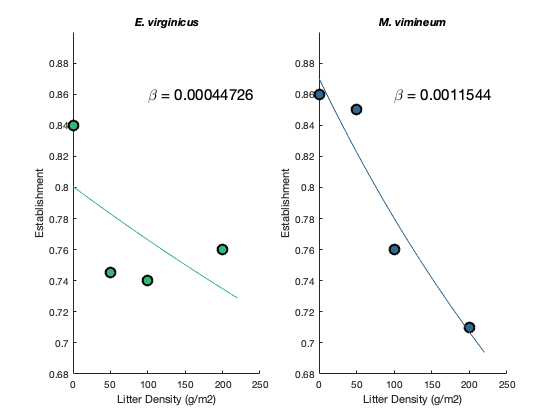

x = linspace(0,max(litter_densities)*1.1,1000);
[YPRED, DELTA] = nlpredci(modelfun, x,Mv_E_coef, R, 'cov', CovB);
subplot(1,2,2)
scatter(litter_densities, Mv_establishment, 'filled', 'MarkerEdgeColor','black',...
    'MarkerFaceColor',Mv_Color,'LineWidth',2,'SizeData',100)
hold on; plot(x,YPRED, 'Color', Mv_Color); hold off;
ylim([0.68,0.9])
xlabel('Litter Density (g/m2)'); ylabel('Establishment');
title('\itM. vimineum');
text(100,0.86, ['\beta = ', num2str(exp(Mv_E_coef(2)))], 'FontSize', 15)

Now we collect the estimates of beta, and find that *Microstegium *is 2.58 times more sensitive to litter than *Elymus virginicus *in this experiment given the best fit model.

betaA = exp(Mv_E_coef(2));
betaP = exp(Ev_E_coef(2));

beta_ratio = betaA/betaP

beta_ratio = 2.5810

## Estimating $R_0$

The reproductive number for the annual is

    $R_{0A} = \frac{g_Ae_Ay_A}{1-s_A(1-g_A)}$.

We have the following estimates from the literature (and their sources):

sA = 0.15; % Redwood et al. (2018);  
gA = 0.79;  yA = [6000 7000]; % Wilson et al. (2015)
eA = [0.53 0.96]; % Emery et al. (2013); Warren et al. (2013). 
% The nonlinear regression of eA from above is within this range, so we
% keep the range as a measure of uncertainty in the estimate.

There is uncertainty in the basic reproductive number because we have a range of values for $y_A$ and $e_A$. One way to characterize this uncertainty is by the minimum, median, and maximum values of the distribution. 

R0A_median = mean(yA)*gA*mean(eA)/(1 - sA*(1-gA));
R0A_minmax = yA*gA.*eA/(1 - sA*(1-gA));
R0A = [R0A_minmax(1),R0A_median, R0A_minmax(2)]

R0A = 	1.0e+03 *

    2.5939    3.9500    5.4815


The reproductive number for the perennial is 

    $R_{0P} = \frac{g_Pe_Py_P}{1-s_P(1-g_P)}\left(f + \frac{p_S}{1-p_P} \right) = \frac{g_Pe_Py_P}{1-s_P(1-g_P)}\left(f + T_P \right)$,

where $T_P = p_S/(1-p_P)$ is the expected vegetative lifetime of a perennial plant in years (i.e., lifetime not counting life as a seed) as derived in SI section S2 "Expected lifetime of the perennial plant". We have the following estimates from the literature (and their sources):

sP = 0.05; gP = 0.8; % Garrison and Stier (2010)
yP = [390,435];  % Stevens (1957)
eP = Ev_E_coef(1); % From nonlinear regression abvoe using data from Benetiz et al. (2022) 

We could not find direct estimates of $p_S$, $p_P$, and $f$, which isn't too surprising considering these are stage-specific attributes of a species, and typically only species-level data is reported. We assume that $f$ ranges from 50% - 100%, i.e., first-year plants produce on average somewhere between one quarter and three-quarter the seed of an established plant. 

f = [0.25,0.75]; 

For $p_S$ and $p_P$, first recognize that in the analysis of competitive outcomes, the only relevant measures are $R_0$, $\beta$, and $\hat{L}^{\{-i\}}$. The parameters $p_S$ and $p_P$ are present in $R_{0P}$ and $\hat{L}^{\{-A\}}$ as non-separable parameters in the composite parameter $p_S/(1-p_P)$. The analysis in SI section S2, "Expected Lifetime of Perennial Plant" shows that $p_S/(1-p_P)$ is the expected lifetime of the vegetative state of the perennial, which we denote as $T_P$. The USDA PLANTS database identifies the lifespan of *Elymus virginicus *as "short", and so we assign a range from 1.5 to 7.5 years as the lifespan of 

T_P = [1.5,7.5]; % Assumed based on short lifespan description from USDA PLANTS Database

Again, we will calculate the minimum, median, and maximum values of lambda.

R0P_minmax = gP.*yP.*eP.*(f + T_P)./(1 - sP.*(1-gP));
R0P_median = mean(gP)*mean(yP)*mean(eP)*(mean(f) + mean(T_P))/(1 - mean(sP)*(1-mean(gP)));
R0P = [R0P_minmax(1), R0P_median, R0P_minmax(2)]

R0P = 	1.0e+03 *

    0.4415    1.3343    2.3218


Using these distributions of $R_0$s, who is the dominant under direct competition when litter has neglibigle effect?

The ratio's of reproductive numbers give an indication of who is dominant. 

lambda_ratio = R0A'./R0P

lambda_ratio =     5.8746    1.9440    1.1172
    8.9458    2.9603    1.7013
   12.4143    4.1080    2.3609


Here is a plot of all possible combinations of min, median, and max values of $R_0$ for the two species. The solid line is a 1:1 line. Above the line, *Elymus* has larger $R_0$. Below the line, *Microstegium *has larger $R_0$.

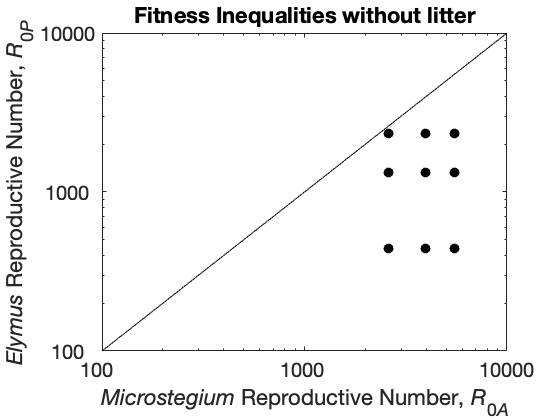

R0_max = max([R0A, R0P]);
figure()
loglog([1,20*R0_max], [1,20*R0_max], 'color', 'black');
hold on
for i = 1:length(R0A)
    scatter(R0A(i)*ones(1,length(R0P)), R0P,...
        100, 'filled', 'CData', zeros(1,3))
end
hold off
xlabel('{\itMicrostegium} Reproductive Number, {\itR}_{0{\itA}}');
ylabel('{\itElymus} Reproductive Number, {\itR}_{0{\itP}}')
set(gca, 'FontSize', 20);
title('Fitness Inequalities without litter')
axis([10^2, 10^4, 10^2, 10^4])
ax = gca; ax.XTick = 10.^[2:4]; ax.YTick = 10.^[2:4];
ax.XTickLabels = [100,1000,10000];
ax.YTickLabels = [100,1000,10000];

It looks here like most of our evidence suggests that *Microstegium* is a better competitor than *Elymus*, which fits with our prior expectations.

## Evaluating Potential Tradeoffs

The evidence here points to a clear tradeoff between $\beta$ and $R_0$ where *Microstegium *has higher lifetime reproduction but is also more sensitive to litter. We can visualize this tradeoff by plotting $\beta$ and $R_0$.

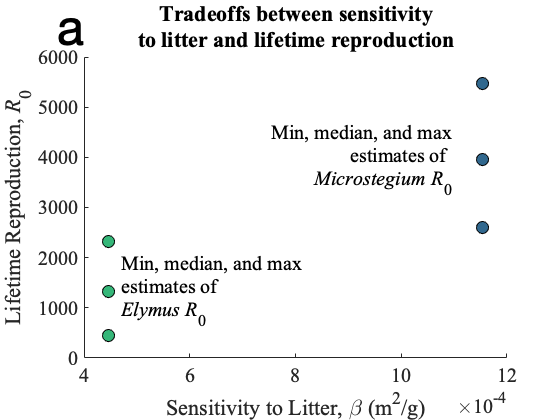

figure()
colors = viridis(4);
scatter(betaA*ones(1,3), R0A, 'filled', 'MarkerFaceColor', Mv_Color,...
    'MarkerEdgeColor', 'black', 'SizeData', 150, 'LineWidth', 1);
hold on;
scatter(betaP*ones(1,3), R0P, 'filled', 'MarkerFaceColor', Ev_Color,...
    'MarkerEdgeColor', 'black', 'SizeData', 150, 'LineWidth', 1);
ax = gca; xlabel('Sensitivity to Litter, \beta (m^2/g)'); ylabel('Lifetime Reproduction, {\itR}_0');
title({'Tradeoffs between sensitivity', 'to litter and lifetime reproduction'})
ax.FontSize = 20; ax.FontName = 'Times New Roman';
text(0.95*betaA, R0A_median, {'Min, median, and max','estimates of ','{\itMicrostegium} {\itR}_0'}, "FontSize",20,...
    'FontName', 'Times New Roman', 'HorizontalAlignment','right', 'VerticalAlignment','middle');
text(1.05*betaP, R0P_median, {'Min, median, and max','estimates of','{\itElymus} {\itR}_0'}, "FontSize",20,...
    'FontName', 'Times New Roman', 'HorizontalAlignment','left', 'VerticalAlignment','middle');
text(0,1,'a', 'Units','normalized', 'VerticalAlignment','bottom', 'HorizontalAlignment','right',...
    "FontSize",50, 'FontName', 'Helvetica')

We can also ask whether the species with the larger $R_0$ has the larger $L^*$.

The L*s for the species are

LstarA = (R0A - 1)/betaA

LstarA = 	1.0e+06 *

    2.2462    3.4209    4.7475


LstarP = (R0P - 1)/betaP

LstarP = 	1.0e+06 *

    0.9850    2.9812    5.1889


And L*s plotted against one another show that *Elymus *is, in general, a dominant competitor in the presence of litter. 

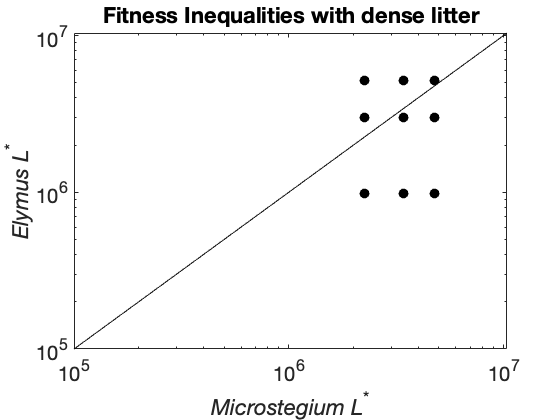

Lstar_max = max([LstarA, LstarP]);
figure()
loglog(2*[1,Lstar_max], 2*[1,Lstar_max], 'color', 'black');
hold on
for i = 1:length(LstarA)
    scatter(LstarA(i)*ones(1,length(LstarP)), LstarP,...
        100, 'filled', 'CData', zeros(1,3))
end
hold off
xlabel('{\itMicrostegium L}^*'); ylabel('{\itElymus L}^*')
set(gca, 'FontSize', 20); axis([100000,2*Lstar_max, 100000, 2*Lstar_max])

title('Fitness Inequalities with dense litter')

For 4 of the 9 possible combinations of $R_{0A}$ and $R_{0P}$, *Elymus *has the larger $L^*$. Otherwise, *Microstegium *has the larger estimated $L^*$, despite its higher sensitivity to litter overall. Its much larger lifetime reproduction makes up for its greater sensitivity to litter, according to the model. 

## Litter Densities in Monoculture

The next step is to calculate the values of $\alpha$. The value of $\alpha$ in the model is presented as a per-seedling effect, which can be estimated using competition experiments. However, these are very sensitive to the scale of the experiments and the densities of the plants used. An alternative approach is to recognize that the only practical role of $\alpha$ in the model is to control equilibrium plant density. It plays almost no role in coexistence of species, except indirectly through litter production through its effect on total popualtion size. Instead of calculating $\alpha$ directly, we use observations of population density the field to fit values of $\alpha$*. *This approach much more directly estimates the functional effect of $\alpha$ rather than its interpretational effect in the model. 

## Litter sensitivity and production

The final measure to estimate is $\hat{L}^{\{-i\}}$, the density of litter accumulated by a species $j$ as resident (i.e., with species $i$ absent) at equilibrium. We cannot find direct measures of this quantity, so we instead try to estimate it from the derived expression of the model. 

For the annual as resident, the equilibrium litter is given by the following quadratic solution

    $\hat{L}^{\{-P\}} = \frac{1}{2}\left( \frac{b_T}{d} - \frac{1}{\beta_A} - \frac{b_A}{d\alpha_A} \right) + \sqrt{ \frac{1}{4} \left( \frac{b_T}{d} - \frac{1}{\beta_A} - \frac{b_A}{d\alpha_A} \right)^2 + \frac{1}{\beta_A}\left( \frac{b_T}{d} + \frac{b_A}{d\alpha_A}(R_{0A}-1) \right) }$.

Note that $b_T$ and $d$ are environmental parameters and not species properties (we will set these values later). The parameters $\beta_A$ and $R_{0A}$ are already estimated above. We are left to estimate the parameters $b_A$ and $\alpha_A$. But, notice that these two are always present together as $b_A/\alpha_A$. Therefore, if we can estimate this composite parameter, then that is sufficient to be able to estimate $\hat{L}^{\{-P\}}$. 

The key to estimating $b_A/\alpha_A$ is to recognize that the reciprocal, $\alpha_A/b_A$ is the competition coefficient in units of biomass of the annual plant. As such, an equivalent model to the one in the main text, but written in terms of biomass density rather than indvidual density will have biomass-scaled competition coefficients. We can use this new model written in terms of biomass density with estimates of biomass density from Flory et al. (2017). We stress that using a model in terms of biomass changes nothing about the dynamics of the model, it only changes the units. 

Let $B_A(t) = b_Ag_AE_A(t)N_A(t)$ be the density of annual biomass in year $t$, where $b_A$ is the biomass of an individual annual. Likewise let $B_S(t) = b_Pg_PE_P(t)N_S(t)$ be the biomass density of the perennials in their first year, and $B_P(t) = b_PN_P(t)$ be the biomass density of established perennial plants. 

Writing the competition function (the denominator of eq. 5) in the main text in terms of biomass yields

    
$$C(t) = 1 + \frac{\alpha_A}{b_A}B_A(t) + \frac{\alpha_P}{b_P}\Big(B_P(t) + \gamma B_S(t) \Big)$$


As you can see, the biomass scaled competition coefficients for the two species, $\alpha_j/b_j$, are present in this expression.

When the annual is alone at equilibrium, eq. (S22) shows that the magnitude of competition is equal to $R_{0A}/(1 + \beta_A \hat{L}^{\{-P\}})$. Thus, we have the following relationship between the biomass scaled competition coefficient and annual biomass density as a resident, 

    $\frac{\alpha_A}{b_A} = \left(\frac{R_{0A}}{1 + \beta_A\hat{L}^{\{-P\}}} - 1 \right) \frac{1}{\hat{B}_A^{\{-P\}}}$.

Unfortunately, this is a function of equilibrium litter, which we are trying to estimate. Flory et al. (2017) run invasion experiments in 5m $\times$ 5m plots and follow the plots for multiple years with plant biomass harvested in some subset of plots each year. In plots with *Microstegium*, native plant densities are negligible (*Microstegium *biomass is near 100% of total plot biomass), and so we take these plots as monoculture. Very little litter built up in the first 4 years of the experiment (2006-2009), and so we use the average biomass of these plots as the biomass values and set $(\hat{L}^{\{-P\}} = 0)$. This allows us to estimate $\alpha_A/b_A$ using our prior estimates of $R_{0A}$ and the data from Flory et al (2017) on biomass density. When $\hat{L}^{\{-P\}} = 0$, a reasonble estimate of $\alpha_A/b_A$ is

    $\alpha_A/b_A = \text{exp}\big\{\mathrm{ln}(R_{0A} - 1) - \overline{\mathrm{ln}(\hat{B}_A)} \big\}$,

where the bar indicates a simple average. 

The mean biomass density on the log scale during 2006-2009 from Flory et al. (2017) is

ln_micro_biomass_density = 5.8219; % units: log(grams/m^2)
micro_biomass_density = exp(ln_micro_biomass_density) %units: grams/m^2

micro_biomass_density = 337.6129

Hence, an estimate for $\alpha_A/\beta_A$ is

alphaA_biomass = (R0A - 1)/exp(ln_micro_biomass_density) 

alphaA_biomass =     7.6801   11.6968   16.2330


%units: m^2/g;

Instead of using these estimates, we use the functional relationship between $\alpha_j/b_j$ and equilibrium plant biomass to create the coexistence diagrams. This is because we need to create invasion boundaries as a function of $R_{0A}$ and $R_{0P}$. Since $\alpha_j/b_j$ is a function of $R_{0j}$, it's values change along the phase space, given fixed biomass density. 

We can now substitute these relationships into the equation for $\hat{L}^{\{-P\}}$, which give

    $\hat{L}^{\{-P\}} = \frac{1}{2}\left( \frac{b_T}{d} - \frac{1}{\beta_A} - \frac{\hat{B}_A^{\{-P\}}}{d(R_{0A}-1)} \right) + \sqrt{ \frac{1}{4} \left( \frac{b_T}{d} - \frac{1}{\beta_A} -\frac{\hat{B}_A^{\{-P\}}}{d(R_{0A}-1)} \right)^2 + \frac{1}{\beta_A}\left( \frac{b_T}{d} + \frac{\hat{B}_A^{\{-P\}}}{d} \right) }$.

In this expression, the only missing values are $b_T$ and $d$, which we choose later.

We can use the same argument for *Elymus*. The equilbirium litter accumulated by the perennial as resident is 

    $\hat{L}^{\{-A\}} = \frac{1}{2}\left(\frac{b_T}{d} + \frac{1}{\beta_P} - \frac{b_P\prime}{d\alpha_P\prime} \right) + \sqrt{ \frac{1}{4}\left(\frac{b_T}{d} + \frac{1}{\beta_P} - \frac{b_P\prime}{d\alpha_P\prime} \right)^2 + \frac{1}{\beta_P}\left( \frac{b_T}{d} + \frac{b_P\prime}{\alpha_P\prime d}(R_{0P}-1)\right)}$,

where $b_P\prime = b_P(\delta + 1/T_P)$ and $\alpha_P\prime = \alpha_P(1 + \gamma/T_P)$. We have no information about $\gamma$ and so assume that it takes the value $\gamma = 1$, meaning that the competitive effect of perennial plants is constant across individual age. We have now that the biomass scaled competition coefficient is 

 $\frac{b_P\prime}{\alpha_P\prime} = \frac{b_P}{\alpha_P} \left(\frac{\delta + 1/T_P}{1 + 1/T_P}\right)$,

which requires a value of $\delta$ to estimate. Approximately 45% of *Elymus *biomass is retained at the end of the growing season in a greenhouse experiment (Amy E. Kendig, unpublished data). Thus the amount of litter lost for a surviving individual is $\delta$ = 0.55.

delta = 0.55;

Now we need an estimate for $\alpha_P/b_P$, which we can get by taking the same approach for *Elymus *as we did for *Microstegium*. Recognize first that total perennial biomass at equilibrium is  

      $\frac{\alpha_P}{b_P} = \left(\frac{R_{0P}}{1 + \beta_P\hat{L}^{\{-A\}}} - 1 \right) \left( \frac{1}{\hat{B}_P^{\{-A\}}+\gamma\hat{B}_S^{\{-A\}}} \right)$.

In the control plots in in Flory et al. (2017), there is no *Microstegium, *meaning that these are suitable experiments for perennial density as resident. There was negligible litter in these plots early in the experiment, so again we assume $L = 0$ and use biomass density harvested from these plots in the first four years. Therefore, we have the following expression for the biomass scaled competition coefficient: 

    $\frac{\alpha_P}{b_P} = \frac{R_{0P} - 1}{\hat{B}_P^{\{-A\}}+\hat{B}_S^{\{-A\}}}$.

The average biomass density of graminoids on the log scale in these plots is

ln_elymus_biomass_density = 4.8343; 
% units:log(grams/m^2)
elymus_biomass_density = exp(ln_elymus_biomass_density) %units: grams/m^2

elymus_biomass_density = 125.7505

This means that the estimate for $\alpha_P/b_P$ is 

alphaP_biomass = (R0P - 1)./exp(ln_elymus_biomass_density)

alphaP_biomass =     3.5033   10.6031   18.4552


%units: m^2/gram;

Again, using the relationship between $\alpha_P/b_P$ and plant biomass density, the expression for equilbirium litter with the perennial as resident rewrites as

    
$$\hat{L}^{\{-A\}} = \frac{1}{2} \left ( \frac{b_T}{d} + \frac{1}{\beta_P} - \frac{1}{d\alpha_P^b}\left(\frac{\delta + 1/T_P}{1 + \gamma/T_P}\right) \right) + \sqrt{\frac{1}{4} \left ( \frac{b_T}{d} + \frac{1}{\beta_P} - \frac{1}{d\alpha_P^b}\left(\frac{\delta + 1/T_P}{1 + \gamma/T_P}\right) \right)^2 + \frac{1}{\beta_P} \left( \frac{b_T}{d} + \frac{1}{d\alpha_P^b}\left(\frac{\delta + 1/T_P}{1 + \gamma/T_P}\right)(R_{0P} - 1)\right)  }$$


    
$$\hat{L}^{\{-A\}} = \frac{1}{2}\left( \frac{b_T}{d} - \frac{1}{\beta_P} - \frac{\hat{B}_P + \hat{B}_S}{d(R_{0A}-1)}\left(\frac{\delta + 1/T_P}{1 + 1/T_P}\right) \right) + \sqrt{ \frac{1}{4} \left( \frac{b_T}{d} - \frac{1}{\beta_P} -\frac{\hat{B}_P+\hat{B}_S}{d(R_{0A}-1)}\left(\frac{\delta + 1/T_P}{1 + 1/T_P}\right) \right)^2 + \frac{1}{\beta_P}\left( \frac{b_T}{d} + \frac{\hat{B}_P+\hat{B}_S}{d} \left(\frac{\delta + 1/T_P}{1 + 1/T_P}\right)\right) }$$


We now have expression for equilibrium litter written entirely in terms of parameters we can estimate (or reasonably assume). 

Note that we have a range of estimates of $T_P$ from the section above where we calculate $R_{0P}$. For calculation of litter at equilibrium (below), we take the midpoint of this range, although using other values in the range do not affect the qualitative results.

## Species Coexistence Outcomes

The outcome of coexistence depends on the litter accumulated for each species as resident in the presence of litter produced by trees. The final unspecified values of the model are decomposition, $d$, and tree litterfall, $b_T$. We chose $d$ = 0.1 but note that choosing an alternative value does not qualitatively change the results. We chose two values of $b_T$ corresponding to no litter from other sources ($b_T$ = 0) and moderate litter from external sources ($b_T$ = 200 $g/m^2$). 

We have to find the invasion boundaries, which have the general form

    $R_{0i} > R_{0j} \frac{1+\beta_i\hat{L}^{\{-i\}}}{1+\beta_j\hat{L}^{\{-i\}}}$,                

for species *i* as invader adn species *j* as resident. 

To create these lines, we create a vector of values for $R_{0j}$ and calculate values of $\hat{L}^{\{-i\}}$ across the vector. This creates a vector of values for the right hand side of the invasion condition.

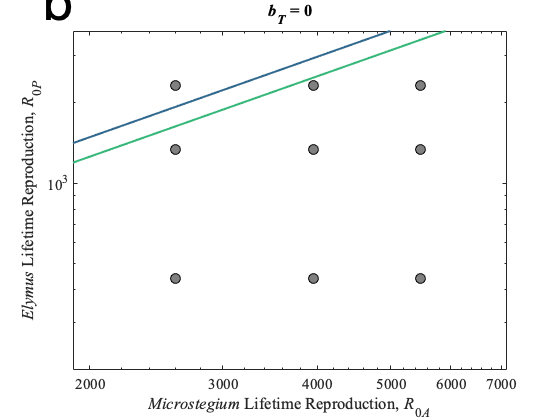

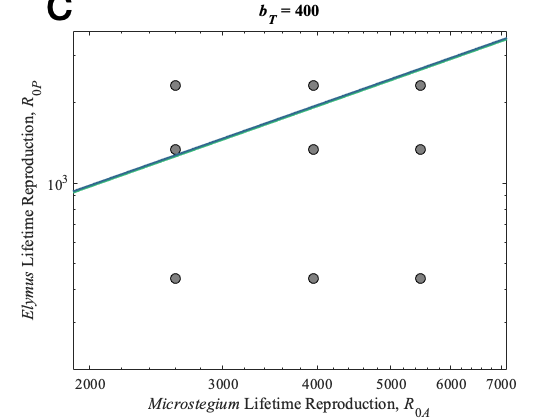

% Values of decomposition and tree litterfall to use in the panels.
dvec = 0.1*ones(1,2);  bTvec = [0,400];

% Differe line types for the different values of elymus relative density.
LABEL = {'b', 'c'};

t = tiledlayout(1,2);
% Loop over the four possible combinations of d and b_T
for k = 1:2

    % Set the values of d and BT
    d = dvec(k); bT = bTvec(k);

    % Create axes
    loglog(0,0,'Color','none', 'HandleVisibility','off');
    xlabel('{\itMicrostegium} Lifetime Reproduction, {\itR}_{0{\itA}}');
    ylabel('{\itElymus} Lifetime Reproduction, {\itR}_{0{\itP}}')
    hold on
    % Plot the estimates of R_0A and R_0P
    for i = 1:length(R0A)
        scatter(R0A(i)*ones(1,length(R0P)), R0P,...
            100, 'filled', 'SizeData', 100,"MarkerEdgeColor",'black',...
            'MarkerFaceColor',0.5*ones(1,3))
    end
    hold off
    set(gca, 'FontSize', 15); set(gca, 'FontName', 'Times New Roman');
    axis([1900, 1.3*max(R0A), 200, 1.6*max(R0P)])

    % Define a vector of values of lambda to create lines
    R0_vec = linspace(0,10*R0_max, 1000);

    %% Plot elymus invasion boundary
    hold on
    % Loop over the three values of elymus relative density

    % Calculate the density of litter produced by microstegium at equilbirium
    alphaA_over_b = (R0_vec - 1)/(micro_biomass_density);
    Leq_A = LitterEq(R0_vec, alphaA_over_b, betaA, 1/d, bT/d);
    % Find the critical values of elymus lambda required to invade.
    R0_P_crit = R0_vec.*(1+betaP*Leq_A)./(1+betaA*Leq_A);
    % Plot this line
    loglog(R0_vec, R0_P_crit, 'Color', Ev_Color,...
        'LineWidth', 2);

    % Now do the same for the invasion boundary of microstegium
    % Calculate elymus competition coefficient with relative density
    % value
    alphaP_over_b = (R0_vec - 1)/(elymus_biomass_density);
    % Calculate eq litter produced by elymus as resident
    Leq_P = LitterEq(R0_vec, alphaP_over_b*(1 + 1/mean(T_P))/(delta + 1/mean(T_P)), betaP, 1/d, bT/d);
    % Calculate critical values of lambda needed for Microstegium to
    % invade
    R0_A_crit = R0_vec.*(1+betaA*Leq_P)./(1+betaP*Leq_P);
    % Plot these critical invasion values
    loglog(R0_A_crit, R0_vec, 'Color', Mv_Color,...
        'LineWidth', 2)

    hold off
    % Label the plot
    title(['{\itb_T} = ', num2str(bT)]);
    t = text(0,1,LABEL{k}, 'Units', 'Normalized', 'HorizontalAlignment', 'right');
    t.FontSize = 50;
    t.VerticalAlignment = 'bottom';
end

## References Cited

Benitez, L., A. E. Kendig, A. Adhikari, K. Clay, P. F. Harmon, R. D. Holt, E. M. Goss, and S. L. Flory. 2022. Invasive grass litter suppresses native species and promotes disease. Ecosphere. 13.

Emery, S. M., S. L. Flory, K. Clay, J. R. Robb, and B. Winters. 2013. Demographic responses of the invasive annual grass Microstegium vimineum to prescribed fires and herbicide. Forest Ecology and Management 308:207–213.

Flory, S. L., J. Bauer, R. P. Philips, and K. Clay. 2017. Effects of a non-native grass invasion decline over time. Journal of Ecology 105:1457-1484.

Garrison, M. A., and J. C. Stier. 2010. Cool-season turfgrass colony and seed survival in a restored prairie. Crop Science 50:345–356.

Redwood, M. E., G. R. Matlack, and C. D. Huebner. 2018. Seed longevity and dormancy state suggest management strategies for garlic mustard (Alliaria petiolata) and Japanese stiltgrass (Microstegium vimineum) in deciduous forest sites. Weed Science 66:190–198.

Stevens, O. A. 1957. Weights of seeds and numbers per plant. Weeds 5:46–55.

Warren, R. J., V. Bahn, and M. A. Bradford. 2013. Decoupling litter barrier and soil moisture influences on the establishment of an invasive grass. Plant and Soil 367:339–346.

Wilson, C. H., T. T. Caughlin, D. J. Civitello, and S. L. Flory. 2015. Combining mesocosm and field experiments to predict invasive plant performance: A hierarchical Bayesian approach. Ecology 96:1084–1092.